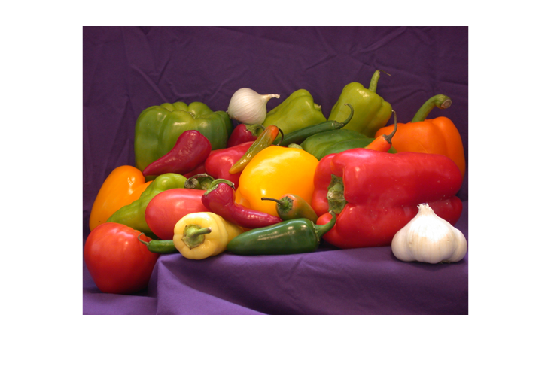

image = imread('peppers.png');
zoomfactor = 2.25;
newimage = imresize(image, zoomfactor);
imshow(image);

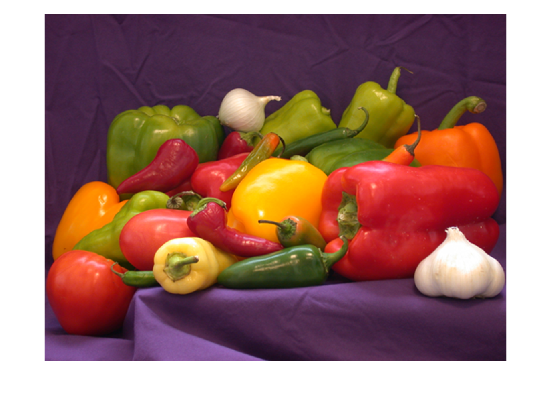

imshow(newimage);

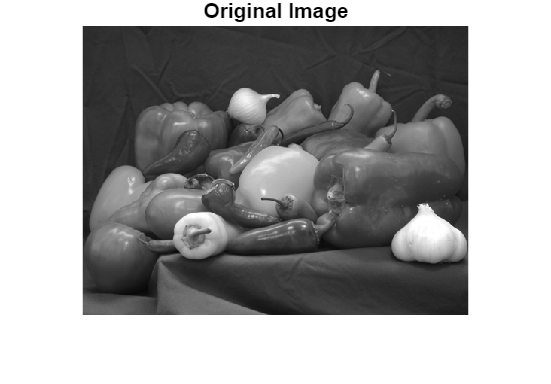


figure;
if size(image,3) == 3
    image = rgb2gray(image);
end
imshow(image);
title("Original Image");

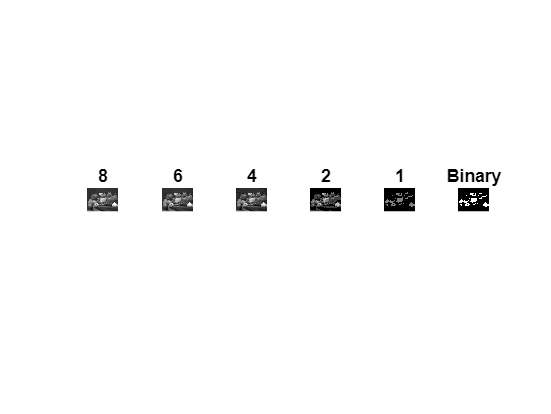

bit_levels = [8,6,4,2,1];

figure;
for i = 1:length(bit_levels)
    bits = bit_levels(i);
    levels = 2^bits;
    new_img = floor(double(image) / (256 / levels)) * (256 / levels);
    new_img = uint8(new_img);
    subplot(1, length(bit_levels) + 1, i);
    imshow(new_img);
    title(num2str(bits));
end

if size(image,3) == 3
    gray_img = rgb2gray(image);
else
    gray_img = image;
end

binary_img = zeros(size(gray_img));
threshold = 128;

for i = 1:size(gray_img,1)
    for j = 1:size(gray_img,2)
        if gray_img(i,j) > threshold
            binary_img(i,j) = 1;
        else
            binary_img(i,j) = 0;
        end
    end
end

subplot(1, length(bit_levels) + 1, length(bit_levels) + 1);
imshow(binary_img);
title('Binary');

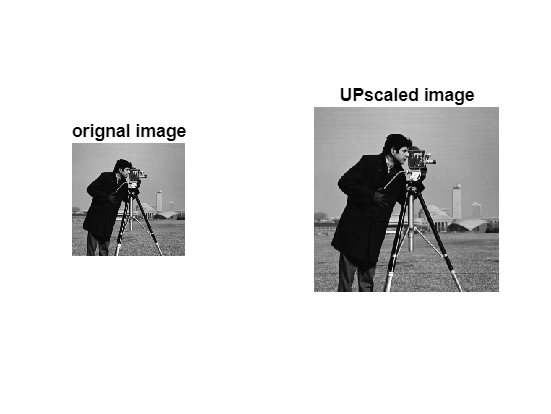



img=imread("cameraman.png");
figure;
subplot(1,3,1);
imshow(img);
title("orignal image");

zoomfac=3;
shrinkfac=0.9;

[m,n]=size(img);

new_m_up=round(m*zoomfac);
new_n_up=round(n*zoomfac);

up_img=zeros(new_m_up,new_n_up,'uint8');
for i=1:new_m_up
    for j=1:new_n_up
        orig_i=ceil(i/zoomfac);
        orig_j=ceil(j/zoomfac);

        orig_i=min(orig_i,m);
        orig_j=min(orig_j,n);
        up_img(i,j)=img(orig_i,orig_j);
    end
end

subplot(1,2,2);
imshow(up_img);
title("UPscaled image");



new_m_up=round(m*shrinkfac);
new_n_up=round(n*shrinkfac);

shrink_img=zeros(new_m_up,new_n_up,'uint8');
for i=1:new_m_up
    for j=1:new_n_up
        orig_i=ceil(i/shrinkfac);
        orig_j=ceil(j/shrinkfac);

        orig_i=min(orig_i,m);
        orig_j=min(orig_j,n);
        shrink_img(i,j)=img(orig_i,orig_j);
    end
end

subplot(1,3,3);
imshow(shrink_img);
title("Downscaled image");

A=zeros(3,3);
A(:)=[10,2,9,4,18,14,22,7,25];
display(A);

A =     10     4    22
     2    18     7
     9    14    25


C=imresize(A,[6,6],"nearest");
display(C);

C =     10    10     4     4    22    22
    10    10     4     4    22    22
     2     2    18    18     7     7
     2     2    18    18     7     7
     9     9    14    14    25    25
     9     9    14    14    25    25


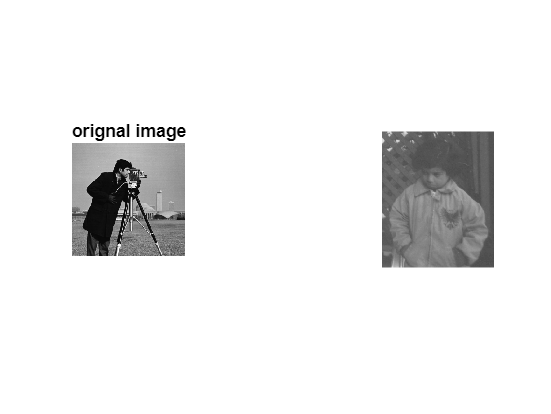


i=imread("pout.tif");
j=imrotate(i,35,'bilinear');
imshow(i);

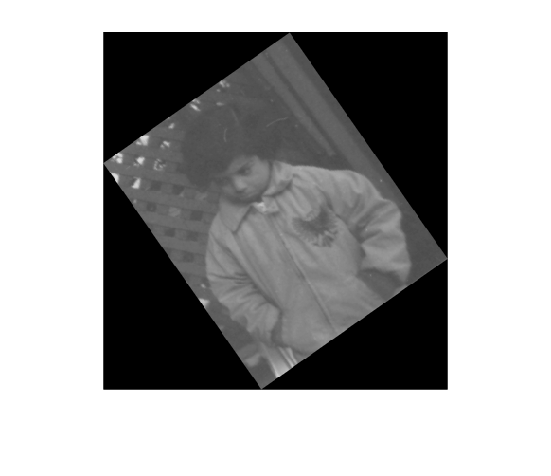

figure, imshow(j);